# LeRoy GCP Ratio Correlation Analysis

**Author:** Scott Campit

## Summary

clear all;

% First we need to clean up the metabolomics dataset
metabolomics = readtable('CCLE_metabolomics_processed.xlsx', 'sheet', 'all');

metabolomics_ccl = extractBefore(string(table2cell(metabolomics(:, 'CCLE_ID'))), '_');
metabolomics(:, 'CCLE_ID') = cellstr(metabolomics_ccl);

% Next, we need to map between datasets
leroy = readtable('LeRoy_et_al.xlsx', 'sheet', 'Single');

[~, ia, ib] = intersect(string(table2cell(metabolomics(:, 'CCLE_ID'))), ...
                        string(table2cell(leroy(:, 'CellLine'))));
                    
% Finally, let's get tables with matching indicies
metabolomics = metabolomics(ia, :);
leroy = leroy(ib, :);

Out of the 12 cancer cell lines that intersect between the LeRoy dataset and the metabolomics dataset, only 6 had intersecting medium. I will use those to compute correlations.

- HL60

- HUH7

- MCF7

- NB4

- SW480

- U937

cellLines2Keep = [          ...
    "HL60", "HUH7", "MCF7", ...
    "NB4", "SW480", "U937"  ...
];

% Get intersection between filtered datasets 
[~, idx] = intersect(table2array(leroy(:, 'CellLine')), cellLines2Keep);
metabolomics = metabolomics(idx, :);
leroy = leroy(idx, :);

## Methylation and acetylation subsets

### Histone markers

leroy_methylation = readtable('LeRoy_et_al.xlsx', 'sheet', 'Methylation');

leroy_methylation = leroy_methylation(ib, :);
leroy_methylation = leroy_methylation(idx, :);

leroy_acetylation = readtable('LeRoy_et_al.xlsx', 'sheet', 'Acetylation');

leroy_acetylation = leroy_acetylation(ib, :);
leroy_acetylation = leroy_acetylation(idx, :);

### Metabolomics

% Methylation
methylation_metabolomics = readtable('CCLE_metabolomics_processed.xlsx', 'sheet', 'Methylation');

methylation_metabolomics = methylation_metabolomics(ia, :);
methylation_metabolomics = methylation_metabolomics(idx, :);

% Acetylation
acetylation_metabolomics = readtable('CCLE_metabolomics_processed.xlsx', 'sheet', 'Acetylation');

acetylation_metabolomics = acetylation_metabolomics(ia, :);
acetylation_metabolomics = acetylation_metabolomics(idx, :);

## Ratios of acetylation to methylation

h3k9_ac_me = table2array(leroy_acetylation(:, 'H3K9ac1')) ./ table2array(leroy_methylation(:, ["H3K9me1", "H3K9me2", "H3K9me3"]))

h3k9_ac_me =     0.0234    0.0110    0.0148
    0.0381    0.0124    0.0148
    0.0345    0.0135    0.0279
    0.0168    0.0263    0.0264
    0.0208    0.0100    0.0117
    0.0175    0.0068    0.0067
    0.0216    0.0104    0.0355
    0.0972    0.0357    0.0401
    0.0506    0.0167    0.0320
    0.0202    0.0071    0.0052


h3k18_ac_me = table2array(leroy_acetylation(:, 'H3K18ac1')) ./ table2array(leroy_methylation(:, ["H3K18me1"]))

h3k18_ac_me =     8.9971
   11.7626
    5.8698
   13.3167
    8.3864
    8.6421
   15.4362
   18.4699
   12.9516
    8.3463


h3k23_ac_me = table2array(leroy_acetylation(:, 'H3K23ac1')) ./ table2array(leroy_methylation(:, ["H3K23me1"]))

h3k23_ac_me =    39.7250
   41.9171
   44.0691
  120.3612
   31.4486
   15.3539
  109.7605
   21.2985
   55.5944
    6.7441


h3k27_ac_me = table2array(leroy_acetylation(:, 'H3K27ac1')) ./ table2array(leroy_methylation(:, ["H3K27me1", "H3K27me2", "H3K27me3"]))

h3k27_ac_me =     0.0058    0.0032    0.0071
    0.0045    0.0087    0.0210
    0.0391    0.0268    0.1785
    0.0172    0.0066    0.0170
    0.0020    0.0004    0.0007
    0.0412    0.0105    0.0148
    0.0114    0.0045    0.0087
    0.0157    0.0049    0.0095
    0.0411    0.0371    0.1289
    0.0044    0.0007    0.0007


ACME = [h3k9_ac_me, h3k18_ac_me, h3k23_ac_me, h3k27_ac_me]

ACME =     0.0234    0.0110    0.0148    8.9971   39.7250    0.0058    0.0032    0.0071
    0.0381    0.0124    0.0148   11.7626   41.9171    0.0045    0.0087    0.0210
    0.0345    0.0135    0.0279    5.8698   44.0691    0.0391    0.0268    0.1785
    0.0168    0.0263    0.0264   13.3167  120.3612    0.0172    0.0066    0.0170
    0.0208    0.0100    0.0117    8.3864   31.4486    0.0020    0.0004    0.0007
    0.0175    0.0068    0.0067    8.6421   15.3539    0.0412    0.0105    0.0148
    0.0216    0.0104    0.0355   15.4362  109.7605    0.0114    0.0045    0.0087
    0.0972    0.0357    0.0401   18.4699   21.2985    0.0157    0.0049    0.0095
    0.0506    0.0167    0.0320   12.9516   55.5944    0.0411    0.0371    0.1289
    0.0202    0.0071    0.0052    8.3463    6.7441    0.0044    0.0007    0.0007


ACME(isnan(ACME)) = 0;
ACME(ACME==inf) = max(ACME(isfinite(ACME)));

### Compute correlations between acetylation:methylation ratios and the raw metabolomics data

leroy_ratios = ["H3K9 ac/me1", "H3K9 ac/me2", "H3K9 ac/me3", ...
              "H3K18 ac/me1", "H3K23 ac/me1", ...
              "H3K27 ac/me1", "H3K27 ac/me2", "H3K27 ac/me3"];

#### Acetylation metabolomics and GCP ratios

First we'll get the metabolomics data we need

acetylation_metabolomics(:, ["CCLE_ID", "DepMap_ID"]) = [];
ac_metabolites = string(acetylation_metabolomics.Properties.VariableNames);
acetylation_metabolomics = table2array(acetylation_metabolomics);

Next, we'll compute the correlation between the GCP ratios and the acetylation metabolomics

[acme_acetylation_corr, acme_acetylation_pval] = corr(ACME, acetylation_metabolomics)

acme_acetylation_corr =     0.2323   -0.2183   -0.0268    0.0682   -0.2474   -0.2809    0.1686   -0.0131   -0.5550   -0.3891    0.0538    0.1615   -0.0160    0.2448   -0.1184    0.3349    0.2662    0.1091    0.3000    0.1314    0.4022   -0.0271    0.1002   -0.3081    0.0520
    0.4801   -0.1215    0.0049   -0.0518   -0.0733   -0.4555   -0.1818   -0.0696   -0.4234   -0.4040    0.1060    0.1554   -0.2265    0.2185    0.0031    0.4031    0.2702    0.1707    0.3987    0.3683    0.5285   -0.1844   -0.3181   -0.1518   -0.1000
   -0.0121    0.2486   -0.2924   -0.2663   -0.0068   -0.6106   -0.2355   -0.3334   -0.3638    0.0404   -0.1293    0.0393   -0.1922    0.5613    0.0047   -0.0071   -0.1329   -0.1332    0.0259   -0.0585    0.1884   -0.6115   -0.3968   -0.7007   -0.3586
   -0.0014   -0.0701   -0.1970   -0.0985    0.0760   -0.4900   -0.1115   -0.1110   -0.4520   -0.1264    0.1285    0.3178    0.0987    0.1852    0.0085    0.2805    0.2383    0.1121    0.2873    0.1811    0.2391    0.0104   

acme_acetylation_pval =     0.4674    0.4954    0.9340    0.8331    0.4383    0.3765    0.6004    0.9678    0.0610    0.2112    0.8681    0.6160    0.9607    0.4432    0.7139    0.2873    0.4030    0.7358    0.3434    0.6840    0.1949    0.9334    0.7567    0.3300    0.8724
    0.1142    0.7068    0.9880    0.8729    0.8208    0.1367    0.5717    0.8298    0.1702    0.1928    0.7431    0.6296    0.4791    0.4951    0.9924    0.1939    0.3957    0.5957    0.1992    0.2388    0.0773    0.5661    0.3136    0.6376    0.7573
    0.9702    0.4360    0.3563    0.4028    0.9833    0.0349    0.4613    0.2896    0.2450    0.9008    0.6887    0.9034    0.5495    0.0576    0.9885    0.9826    0.6805    0.6799    0.9362    0.8568    0.5576    0.0346    0.2016    0.0111    0.2523
    0.9965    0.8287    0.5394    0.7608    0.8145    0.1058    0.7301    0.7312    0.1402    0.6955    0.6907    0.3142    0.7602    0.5645    0.9792    0.3771    0.4557    0.7287    0.3652    0.5732    0.4541    0.9743   

mask = acme_acetylation_corr;
mask(acme_acetylation_pval > 0.05) = NaN;

Finally, we'll plot the data as a heatmap

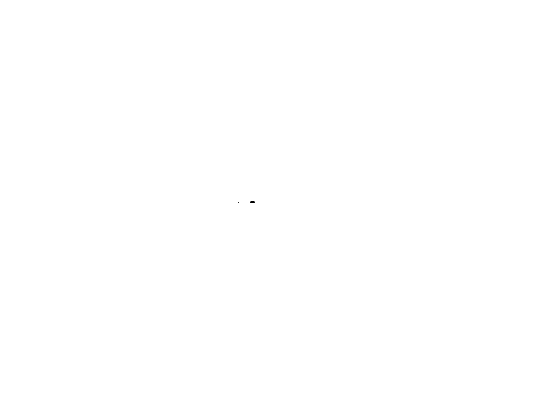

redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
ac_metabolites = strrep(ac_metabolites, '_', ' ');
heatmap(mask', ...
        'colormap', redbluecmap, ...
        'YData', ac_metabolites, ...
        'XData', leroy_ratios, ...
        'FontSize', 45)

#### Methylation metabolomics and GCP ratios

First we'll get the metabolomics data we need

methylation_metabolomics(:, ["CCLE_ID", "DepMap_ID"]) = [];
me_metabolites = string(methylation_metabolomics.Properties.VariableNames);
methylation_metabolomics = table2array(methylation_metabolomics);

Next, we'll compute the correlation between the GCP ratios and the acetylation metabolomics

[acme_methylation_corr, acme_methylation_pval] = corr(ACME, methylation_metabolomics)

acme_methylation_corr =     0.2281   -0.2809    0.1686   -0.2265    0.3716   -0.4562    0.1770    0.2069    0.3147    0.3608   -0.1200    0.4950   -0.1657    0.2864
    0.4443   -0.4555   -0.1818    0.2015    0.2165   -0.2506    0.2415    0.2313    0.1355    0.2647    0.0385    0.1467   -0.5053    0.0716
   -0.1517   -0.6106   -0.2355    0.1910   -0.1096   -0.3039   -0.1318   -0.0268   -0.2464   -0.1033    0.1359   -0.1263   -0.0499   -0.1615
    0.2380   -0.4900   -0.1115   -0.0212    0.1740   -0.1173    0.2054    0.1991    0.2901    0.3935    0.0045    0.2789   -0.3067   -0.2802
   -0.0965   -0.1919   -0.2286    0.7185   -0.2675    0.1511   -0.3834   -0.0812   -0.4445   -0.4706    0.2226   -0.4962    0.0015   -0.3938
    0.0296   -0.6018   -0.4080    0.2447   -0.2877   -0.0661   -0.3315    0.0406   -0.0777   -0.3807   -0.4575    0.0987    0.3668   -0.2723
   -0.1698   -0.4073   -0.3285    0.0557   -0.3172   -0.2977   -0.4862   -0.2262   -0.1018   -0.4048   -0.3816    0.0286    0.4705

acme_methylation_pval =     0.4758    0.3765    0.6004    0.4790    0.2342    0.1361    0.5821    0.5188    0.3191    0.2493    0.7103    0.1018    0.6067    0.3668
    0.1479    0.1367    0.5717    0.5300    0.4992    0.4320    0.4495    0.4694    0.6745    0.4058    0.9055    0.6491    0.0938    0.8249
    0.6379    0.0349    0.4613    0.5521    0.7346    0.3369    0.6830    0.9340    0.4401    0.7494    0.6736    0.6958    0.8777    0.6161
    0.4563    0.1058    0.7301    0.9477    0.5886    0.7166    0.5218    0.5351    0.3603    0.2056    0.9888    0.3801    0.3322    0.3777
    0.7655    0.5502    0.4748    0.0085    0.4006    0.6392    0.2186    0.8019    0.1477    0.1225    0.4868    0.1008    0.9962    0.2053
    0.9272    0.0384    0.1880    0.4433    0.3644    0.8384    0.2925    0.9003    0.8104    0.2221    0.1348    0.7601    0.2409    0.3919
    0.5978    0.1889    0.2971    0.8634    0.3151    0.3474    0.1090    0.4796    0.7529    0.1918    0.2209    0.9297    0.1227

mask = acme_methylation_corr;
mask(acme_methylation_pval > 0.05) = NaN;

Finally, we'll plot the data as a heatmap

me_metabolites = strrep(me_metabolites, '_', ' ');
heatmap(mask', ...
        'colormap', redbluecmap, ...
        'YData', me_metabolites, ...
        'XData', leroy_ratios, ...
        'FontSize', 45)